# Pill detection algorithm

Omar & Javier Machine vision - Task 1

clear;
close all;

## Get images from webcam

%cam = webcam('HD Webcam C615');
%cam.Resolution = '640x480';
camHeight = 480;
camWidth = 640;

## Import images

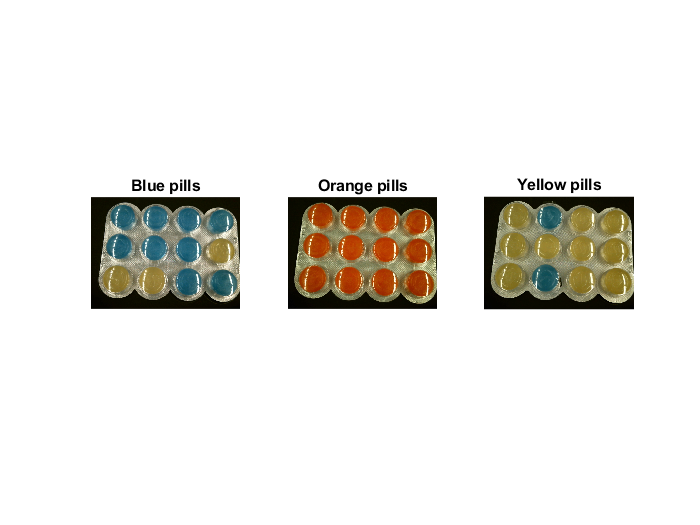

blueImg = imread("pill_pic_blueyellow2.png");
orangeImg = imread("pill_pic_orange2.png");
yellowImg = imread("pill_pic_blueyellow1.png");

figure
subplot(1,3,1);
imshow(blueImg)
title('Blue pills');

subplot(1,3,2);
imshow(orangeImg)
title('Orange pills');

subplot(1,3,3);
imshow(yellowImg)
title('Yellow pills');

% Blue color 
blue_high = [60; 125; 140];
blue_low = [20; 75; 80];

% Orange color 
orange_high = [190; 70; 10];
orange_low = [140; 40; 0];

% Yellow color  
yellow_high = [180; 165; 80];
yellow_low = [120; 100; 20];


% Select image to work with
img = blueImg;

## Extract pixels for each color

% Zeroes framework for the image
blue_pill = zeros(camHeight, camWidth, 1, 'uint8');
orange_pill = zeros(camHeight, camWidth, 1, 'uint8');
yellow_pill = zeros(camHeight, camWidth, 1, 'uint8');

% Looping through every RGB channel and thresholding it
for m = 1: camHeight
    for n = 1: camWidth
        if(((img(m, n, 1) > blue_low(1)) && (img(m, n, 1) < blue_high(1)))...
                && ((img(m, n, 2) > blue_low(2)) && (img(m, n, 2) < blue_high(2)))...
                && ((img(m, n, 3) > blue_low(3)) && (img(m, n, 3) < blue_high(3))))
            blue_pill(m, n) = 255;
        end
        
        if(((img(m, n, 1) > orange_low(1)) && (img(m, n, 1) < orange_high(1)))...
                && ((img(m, n, 2) > orange_low(2)) && (img(m, n, 2) < orange_high(2)))...
                && ((img(m, n, 3) > orange_low(3)) && (img(m, n, 3) < orange_high(3))))
            orange_pill(m, n) = 255;
        end
        
        if(((img(m, n, 1) > yellow_low(1)) && (img(m, n, 1) < yellow_high(1)))...
                && ((img(m, n, 2) > yellow_low(2)) && (img(m, n, 2) < yellow_high(2)))...
                && ((img(m, n, 3) > yellow_low(3)) && (img(m, n, 3) < yellow_high(3))))
            yellow_pill(m, n) = 255;
        end
    end
end

## Image erosion

% 4x4 mask for erosion

eroded_blue = imerode(blue_pill, strel('square',4)); %structuring element

'strel' requires Image Processing Toolbox.

eroded_orange = imerode(orange_pill, strel('square',4)); %structuring element
eroded_yellow = imerode(yellow_pill, strel('square',4)); %structuring element

## Display all images and ROI

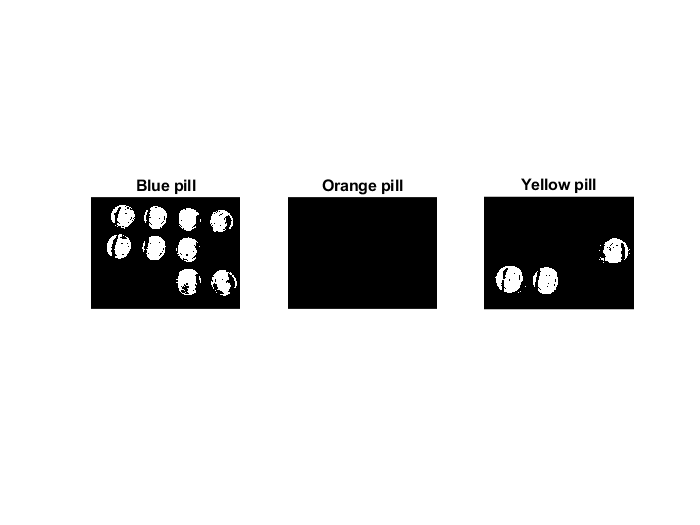

subplot(1,3,1);
imshow(blue_pill)
title('Blue pill');

subplot(1,3,2);
imshow(orange_pill)
title('Orange pill');

subplot(1,3,3);
imshow(yellow_pill)
title('Yellow pill');


blue_cc = bwconncomp(blue_pill);

'bwconncomp' requires Image Processing Toolbox.

numpixels = cellfun(@numel, blue_cc.PixelIdxList);
[blue_largest, blue_id] = max(numpixels)

orange_cc = bwconncomp(orange_pill);
numpixels = cellfun(@numel, orange_cc.PixelIdxList);
[orange_largest, orange_id] = max(numpixels)

yellow_cc = bwconncomp(yellow_pill);
numpixels = cellfun(@numel, yellow_cc.PixelIdxList);
[yellow_largest, yellow_id] = max(numpixels)

## Check the pixel count for each pill

detected_pill = 200;
    
if ((blue_largest > detected_pill) || (orange_largest > detected_pill) || (yellow_largest > detected_pill))
    pill_detected = true
else
    pill_detected = false
end